#  Log Liklihood - Maximum likelihood estimation method (normal distribution) 

Preparation of data (sampling) 

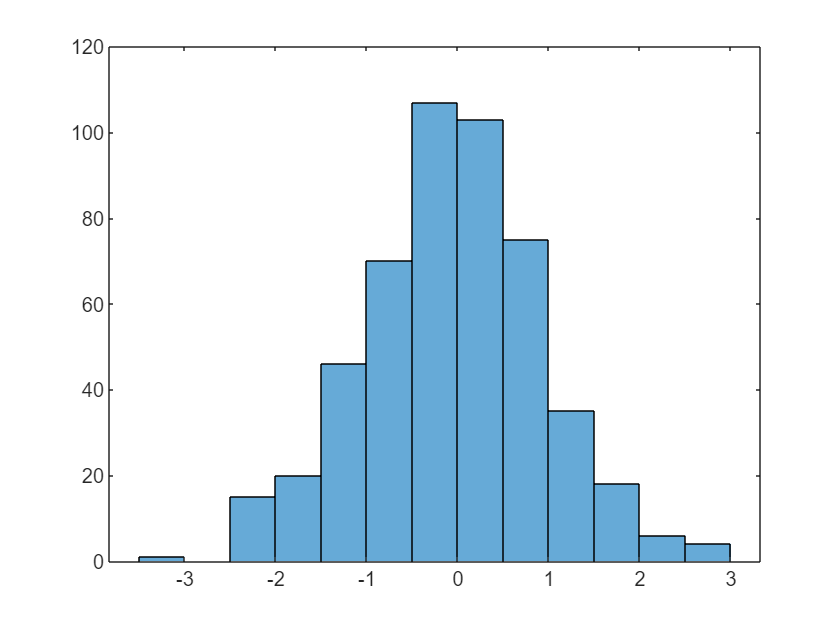

mu = 0;
sigma = 1;
N = 500; % Number of samples
x = randn(N,1); % Sampling
histogram(x);

##  Calculation of log likelihood 

Select estimated parameters ( $\mathbf{\mu}\; \text{and}\; {\Sigma}$ ) 

mu1 = 2.5;
sigma1 = 1.9;

$p(\mathbf{x}|\mathbf{\mu},\Sigma) = \frac{1}{(2\pi)^{M/2}|\Sigma|^{-1/2}}\exp\left[-\frac{1}{2}(\mathbf{x}-\mathbf{\mu})^\top \Sigma^{-1} (\mathbf{x}-\mathbf{\mu})\right]$ Preparation (normal distribution) * Calculate 

pdfx = min(x)-2*sigma1:0.1:max(x)+2*sigma1;
y = normpdf(pdfx,mu1,sigma1);

$L(\mathbf{\mu},\Sigma) = \ln p(\mathbf{x}|\mathbf{\mu},\Sigma)$ (log likelihood) 

L = N*log(1/(sqrt(2*pi)*sigma1)) - 1/2 * sum((x-mu1/sigma1).^2); 

Visualize 

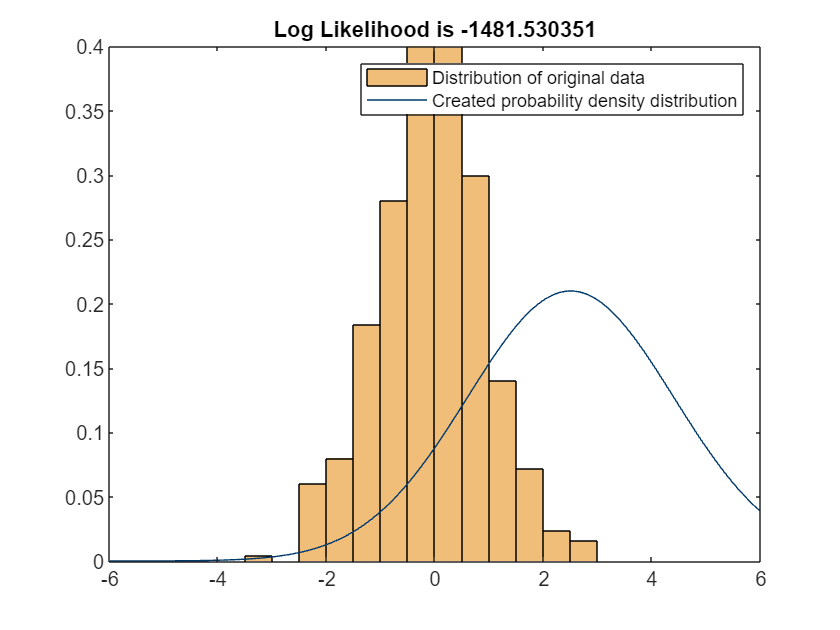

histogram(x,'Normalization','pdf','FaceColor',"#E89222");
line(pdfx,y,'LineStyle','-','Color',"#003A6D");
title(sprintf("Log Likelihood is %f",L));
xlim([-6 6]);ylim([0,0.4]); legend("Distribution of original data","Created probability density distribution");

##  Animation 

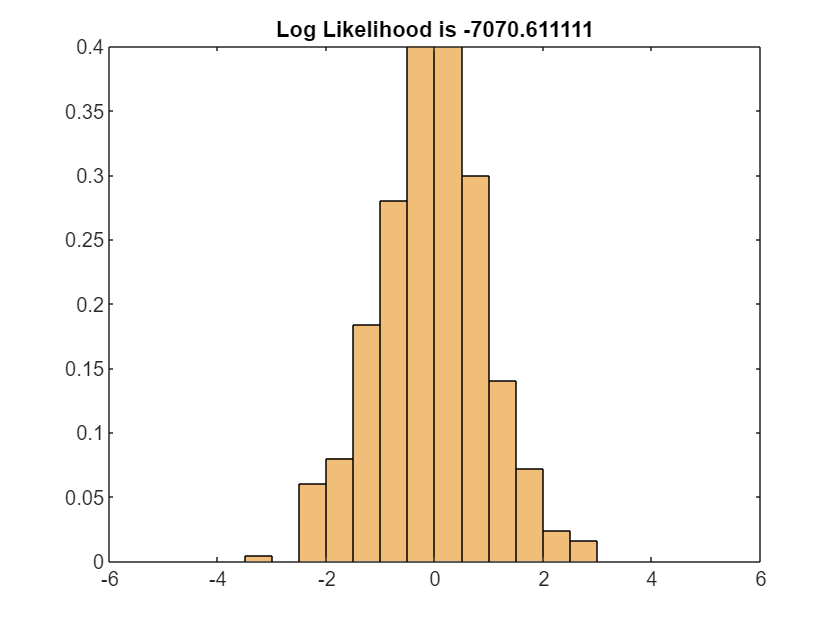

for mu1=linspace(-5,5,100)
    for sigma1=1 %linspace(0.2,3,100)
    %
    pdfx = min(x)-2*85001&sigma1:0.1:max(x)+2*85001&sigma1;
    y = normpdf(pdfx,mu1,sigma1);
    %
    L = N*log(1/(sqrt(2*pi)*sigma1)) - 1/2 * sum((x-mu1/sigma1).^2);
    histogram(x,'Normalization','pdf','FaceColor',"#E89222");
    line(pdfx,y,'LineStyle','-','Color',"#003A6D");
    title(sprintf("Log Likelihood is %f",L));
    xlim([-6 6]);
    ylim([0,0.4]);
    drawnow;
    end
end 